data = load('datasets\datos_iris.mat');
P = data.P; % Patrones de entrada
T = data.T; % Salidas deseadas

Asumimos que el orden de las variedades de lirio es el ofrecido en el enunciado: virgínica, setosa y versicolor. En P tenemos los patrones de entrada formados por las 4 características: longitud del sépalo, ancho del sépalo, longitud del pétalo y ancho del pétalo, en ese orden.

Primero vamos a visualizar todos los datos para observar las características de los mismos.

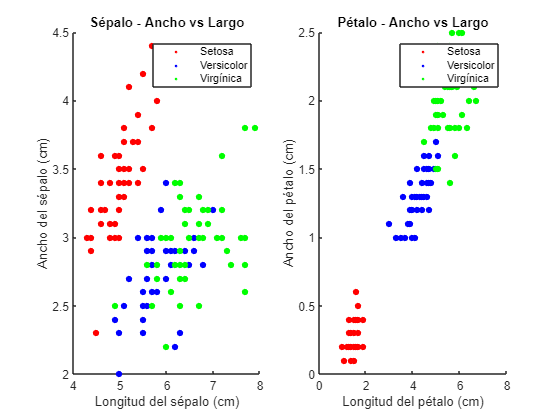

prop_setosa = P(:,1:50);
prop_versicolor = P(:,51:100);
prop_virginica = P(:,101:150);

% Visualizamos los datos
f = figure();
subplot(1,2,1); hold on;
title('Sépalo - Ancho vs Largo');
scatter(prop_setosa(1,:), prop_setosa(2,:), 'r.', 'SizeData', 200);
scatter(prop_versicolor(1,:), prop_versicolor(2,:), 'b.', 'SizeData', 200);
scatter(prop_virginica(1,:), prop_virginica(2,:), 'g.', 'SizeData', 200);
legend('Setosa', 'Versicolor', 'Virgínica');
xlabel('Longitud del sépalo (cm)');
ylabel('Ancho del sépalo (cm)')
subplot(1,2,2); hold on;
title('Pétalo - Ancho vs Largo');
scatter(prop_setosa(3,:), prop_setosa(4,:), 'r.', 'SizeData', 200);
scatter(prop_versicolor(3,:), prop_versicolor(4,:), 'b.', 'SizeData', 200);
scatter(prop_virginica(3,:), prop_virginica(4,:), 'g.', 'SizeData', 200);
legend('Setosa', 'Versicolor', 'Virgínica');
xlabel('Longitud del pétalo (cm)');
ylabel('Ancho del pétalo (cm)');
hold off;

Se puede apreciar como la variedad Setosa es linealmente separable de las otras dos variedades en las dos representaciones. Sin embargo, las otras dos variedades, Virgínica y Versicolor, se solapan entre sí, imposibilitando la separación mediante métodos lineales.

% Creamos la red neuronal
red = feedforwardnet([5 10],'traingd');

% La configuramos
red = configure(red,P,T);

%view(red) % Para visualizar la estructura de la red

% Entrenamos la red neuronal
red.trainParam.epochs = 1000;
red = train(red, P, T);

S = sim(red,P);

Convertimos los vectores de salida a un vector que contenga un 1 en la clase más probable.

[~,max_indexes] = max(S);
aux = [0 0 0]';

for i=1:length(max_indexes)
    aux(max_indexes(i)) = 1;
    S(:,i) = aux;
    aux = [0 0 0]';
end

Obtenemos la matriz de confusión para analizar los resultados obtenidos.

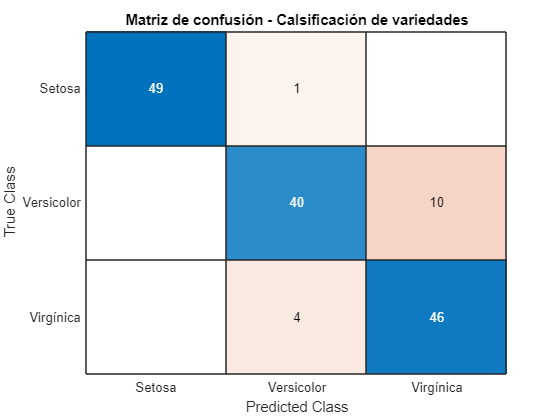

[~,max_aux] = max(T);
C = confusionmat(max_aux,max_indexes);
classLabels = categorical({'Setosa'; 'Versicolor'; 'Virgínica'});
cm = confusionchart(C, classLabels);
cm.Title = 'Matriz de confusión - Calsificación de variedades';